**GENERATE BACKGROUND FIELDS**

This script computes the background electromagnetic field for a 2-D microwave imaging scenario using an in-house Finite Element Method (FEM) solver.

The simulation includes:

- Geometry generation

- Mesh creation

- Material assignment

- Antenna placement

- Forward electromagnetic simulation

- Electric field visualization

- Data export for inverse scattering applications

The configuration represents a canonical microwave imaging setup:

- Square computational domain

- Circular Domain of Interest (DOI)

- Circular antenna array

- Embedded dielectric target

Units are expressed in SI:

- Length      -> meters

- Frequency   -> Hz

- Conductivity-> S/m

clc;
close all;
clear;
addpath('lib');

**PHYSICAL CONSTANTS**

  mu0    :    vacuum permeability

  eps0    :    vacuum permittivity

  c0        :    speed of light in vacuum

mu0  = 4*pi*1e-7;
eps0 = 8.854187817e-12;
c0 = 1/sqrt(mu0*eps0);

**OPERATING FREQUENCY**

The simulation is performed at 1 GHz.

sim.f = 1e9;
sim.omega = 2*pi*sim.f;

**MATERIAL DEFINITIONS**

Three electromagnetic regions are defined:

- Background medium

- Domain of Interest (DOI)

- Embedded target

The complex relative permittivity is modeled as:

-   eps_complex = eps_r - j*sigma/(omega*eps0)

where:

-   eps_r    :    relative dielectric permittivity

-   sigma    :    electrical conductivity

% Background Material

materials.background.epsr  = 20;
materials.background.sigma = 0.01;

% DOI Material

materials.doi.epsr  = 40;
materials.doi.sigma = 0.02;

% Embedded Target Material
% Here the target has the same dielectric properties of the DOI.

materials.target.epsr  = materials.doi.epsr;
materials.target.sigma = materials.doi.sigma;

% Complex Permittivity Computation

materials.background.epsc = ...
    materials.background.epsr ...
    - 1i*materials.background.sigma/(sim.omega*eps0);

materials.doi.epsc = ...
    materials.doi.epsr ...
    - 1i*materials.doi.sigma/(sim.omega*eps0);

materials.target.epsc = ...
    materials.target.epsr ...
    - 1i*materials.target.sigma/(sim.omega*eps0);

**GEOMETRY DEFINITION**

The computational scenario contains:

- Square computational domain

- Circular DOI

- Circular antenna array

- Embedded dielectric target

Geometry dimensions are expressed in meters.

geom.squareSize   = 0.5;
geom.doiRadius    = 0.10;
geom.antennaRing  = 0.12;
geom.nAntennas    = 24;

% Embedded Target

geom.targetRadius = 0.01;
geom.targetCenter = [0.03, 0.03];

**MESH CONTROL PARAMETERS**

The mesh resolution is selected according to the electromagnetic wavelength inside each material.

Rule of thumb:

-   lambda / 10    :    minimum acceptable

-   lambda / 12    :    good FEM accuracy

-   lambda / 15    :    high accuracy

lambda_doi = c0/(sim.f*sqrt(materials.doi.epsr));
lambda_bg  = c0/(sim.f*sqrt(materials.background.epsr));

meshControl.hDOI    = lambda_doi/12;
meshControl.hBG     = lambda_bg/12;
meshControl.hAnt    = lambda_bg/15;
meshControl.hTarget = lambda_doi/12;

% Antenna Circle Radius
% Small antenna circles are used in order to force mesh conformity around the source locations.

meshControl.rAnt = meshControl.hAnt;

**REATE SCENARIO AND FEM MESH**

The function createScenarioMesh() performs:

- Geometry construction

- PDE geometry decomposition

- FEM mesh generation

- Centroid extraction

- Antenna coordinate computation

- DOI cell indexing

scenario = createScenarioMesh(geom, meshControl);

**GEOMETRY VISUALIZATION**

Plot:

- Face IDs

- Edge IDs

- FEM mesh

These plots are useful for debugging geometric regions and assigning different mesh densities.

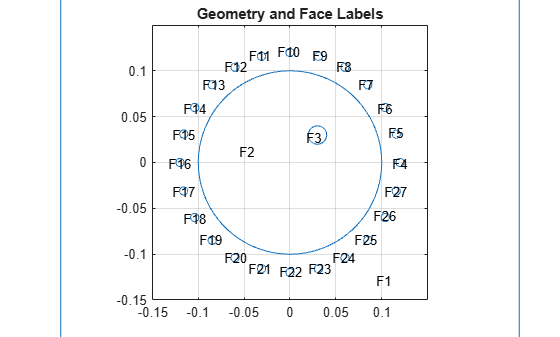

plotGeometry(scenario.model);
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

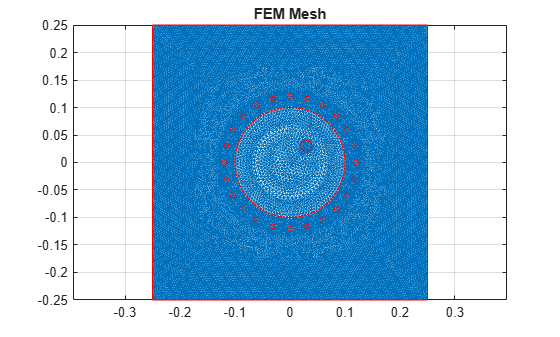

plotMesh(scenario.model);

**MATERIAL ASSIGNMENT TO FEM CELLS**

Complex permittivity is assigned element-wise using triangle centroids depending on its spatial location.

perm = assignPermittivity(...
    scenario.centroids,...
    geom,...
    materials);

**PERMITTIVITY VISUALIZATION**

Two maps are shown:

- Real permittivity distribution

- Imaginary permittivity distribution

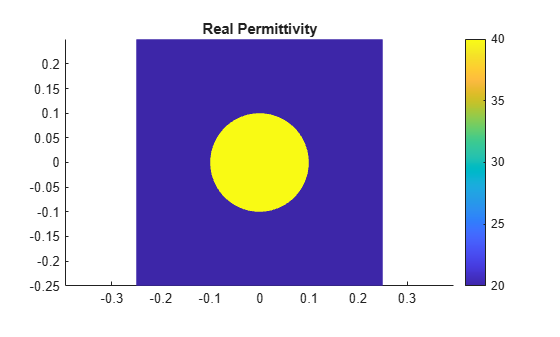

plotPermittivity(...
    scenario.mesh,...
    perm.real,...
    'Real Permittivity');

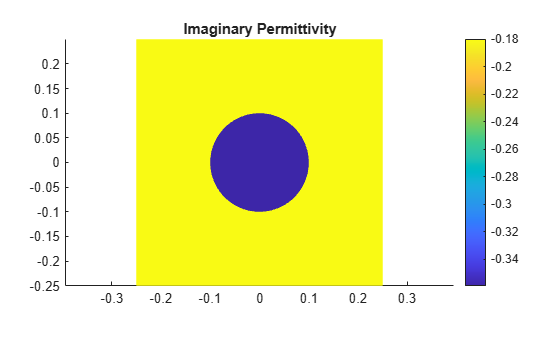


plotPermittivity(...
    scenario.mesh,...
    perm.imag,...
    'Imaginary Permittivity');

**ANTENNA NODE IDENTIFICATION**

Each antenna position is projected onto the nearest FEM node. The resulting indices are used as excitation points in the FEM solver.

probeNodes = findProbeNodes(...
    scenario.mesh.Nodes,...
    scenario.antennaPositions);

**FORWARD FEM SOLUTION**

The function fem2d() computes the electromagnetic field generated by the antenna array inside the heterogeneous dielectric medium.

Outputs:

- Everts    :    field sampled at mesh vertices

- Ecells    :    field sampled at mesh elements

- Area      :    triangle areas

current = 1e-3;

[Everts, Ecells, Area] = fem2d(...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm.complex,...
    sim.f,...
    probeNodes,...
    materials.background.epsc,...
    [],...
    current);

**FIELD VISUALIZATION**

The electric field generated by one transmitting antenna is visualized:

- Field magnitude

- Field phase

selectedAntenna = 1;

fieldData = Ecells(:,selectedAntenna);

plotField(...
    scenario,...
    abs(fieldData),...
    '|E| Field Magnitude', 'V/m');
plotField(...
    scenario,...
    angle(fieldData),...
    'Phase(E)','rad.');
hold on;

**SAVE RESULTS**

Two files are exported:

- geometry.mat

- mesh and geometry information

- background_fields.mat

- electromagnetic field solutions

nameGEO = 'results/geometry';
nameBF  = 'results/background_fields';

freq = sim.f;

save([nameBF,'.mat'],...
    'Ecells',...
    'Everts',...
    'perm',...
    'current',...
    'freq');

% Geometry Data Export

verts = scenario.mesh.Nodes';
cells = scenario.mesh.Elements';

Ind_probes   = probeNodes;
Ind_cells_doi = scenario.cellsDOI;

save([nameGEO,'.mat'],...
    'verts',...
    'cells',...
    'Ind_probes',...
    'Ind_cells_doi',...
    'geom',...
    'Area');
